# PubChem_SDQ_Bibliometrics

Count references and data in PubChem associated with a CID (e.g., from PubMed, Patent, Springer Nature, and Thieme Literature and bioactivity)

% Vincent F. Scalfani, Serena C. Ralph, Ali Al Alshaikh, and Jason E. Bara 
% The University of Alabama
% Version: 1.0, created with MATLAB R2018a

% N.B. PubChem SDQ is used internally by PubChem webpages and is still 
% being rapidly developed.

## Define the PubChem API and SDQ agent base URL

% PubChem API
api = 'https://pubchem.ncbi.nlm.nih.gov/rest/pug/compound/';
% PubChem SDQ agent
sdq = 'https://pubchem.ncbi.nlm.nih.gov/sdq/sdqagent.cgi?outfmt=json&query=';

% set a longer web options timeout
% this prevents a MATLAB timeout if the server is slow to respond.
options_api = weboptions('Timeout', 30);
options_sdq = weboptions('Timeout', 60, 'ContentType','json');

% Retrieve and display a PNG Image of Compound K-252a; CID = 3035817
CID_SS_query = '3035817';

*Replace the above CID value (CID_SS_query) with a different CID number to customize.*

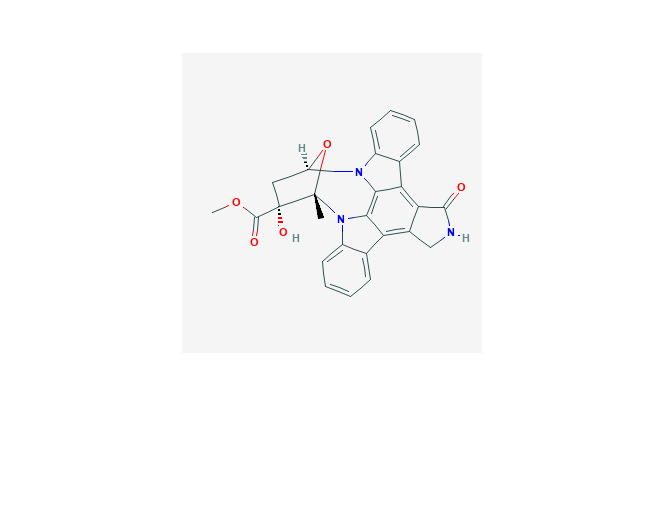

CID_url = [api 'cid/' CID_SS_query '/PNG'];
[CID_img,map] = imread(CID_url);
imshow(CID_img,map)

## Perform a Similarity Search

% Search for chemical structures by Similarity Search (SS), 
% (2D Tanimoto threshold 99% to K-252a; CID = 3035817
api = 'https://pubchem.ncbi.nlm.nih.gov/rest/pug/compound/';
SS_url = [api 'fastsimilarity_2d/cid/' CID_SS_query '/cids/JSON?Threshold=99'];
SS_CIDs = webread(SS_url,options_api);
SS_CIDs = num2cell(SS_CIDs.IdentifierList.CID)

SS_CIDs = 58×1 cell array
    {[  3035817]}
    {[   490561]}
    {[     3813]}
    {[  9981346]}
    {[     3844]}
    {[ 16219545]}
    {[  9912412]}
    {[  9850141]}
    {[   454202]}
    {[ 11612445]}
    {[  9846716]}
    {[   127357]}
    {[134694132]}
    {[102446520]}
    {[ 98053103]}
    {[ 91050674]}
    {[ 90479780]}
    {[  9912410]}
    {[     3814]}
    {[101713437]}
    {[ 98053120]}
    {[ 71684641]}
    {[  9981344]}
    {[118593072]}
    {[ 91325395]}
    {[ 89474445]}
    {[ 89292811]}
    {[ 68771111]}
    {[ 59859198]}
    {[ 59502255]}
    {[ 59102941]}
    {[  9912413]}
    {[  6610352]}
    {[  6610264]}
    {[129090203]}
    {[ 44450630]}
    {[ 24867866]}
    {[ 16760062]}
    {[ 10814623]}
    {[  9890741]}
    {[ 10075889]}
    {[ 10672407]}
    {[ 10743375]}
    {[ 10743829]}
    {[ 25063037]}
    {[ 49868185]}
    {[ 51049453]}
    {[ 91885937]}
    {[ 98043294]}
    {[ 98118654]}
    {[101713435]}
    {[101726258]}
    {[102372026]}
    {[102372027]}
  

*In the above SS_url value, you can adjust to the desired Tanimoto threshold (i.e., 97, 90, etc.)*

% set a CID limit to 100 max

*The CID limit of 100 was added as an initial testing safety for time consideration. This limit can be increased.*

number_SS_CIDs = length(SS_CIDs)

number_SS_CIDs = 58

if number_SS_CIDs > 100
        
        SS_CIDs = SS_CIDs(1:100)      
else
    disp('Number of SS_CIDs not changed')    
end

Number of SS_CIDs not changed


## Retrieve Isomeric SMILES for CIDs, Number of Substances, Literature, Assay, and Bioactivity

% setup a for loop that processes each CID one-by-one.

for j = 1:length(SS_CIDs)
    CID = SS_CIDs{j};
    
    % define api call
    api = 'https://pubchem.ncbi.nlm.nih.gov/rest/pug/compound/';
    % define api call for isomeric SMILES
    CID_IsoSMI_url = [api 'cid/' num2str(CID) '/property/IsomericSMILES/TXT'];
    
    % retrieve isomeric SMILES
    try
        CID_IsoSMI = webread(CID_IsoSMI_url,options_api);     
    catch ME  
        CID_IsoSMI = 'not found'
    end
        n = 0.5;
        pause(n)
            
    % add property data to SS_CIDs data array
    % j increases by 1 on each iteration, so the first CID Isomeric SMILES
    % gets added to {1,2}, the second to {2,2}, third to {3,2}, etc.
        SS_CIDs{j,2} = CID_IsoSMI;
    
    % define sdq call to retrieve count data
    sdq = 'https://pubchem.ncbi.nlm.nih.gov/sdq/sdqagent.cgi?outfmt=json&query=';
    litCountQ_url = [sdq '{"hide":"*","collection":"*","where":{"ands":{"cid":"' num2str(CID) '"}}}'];
    
    try
        litCountQ = webread(litCountQ_url, options_sdq);
    catch ME
        litCountQ = 'not found'
    end
        n = 1;
        pause(n)
        
    % add selected collection count data to SS_CIDs data array
    
    % here the column index values on the left (e.g., {j,3})
    % represent where the data will be stored (column 3), and the values
    % on the right (e.g., litCountQ.SDQOutputSet(2)), is an index value (2),
    % to retrieve the substance count data from the litCountQ.SDQOutputSet 
    % structure array.
        
        % substance
        SS_CIDs{j,3} = litCountQ.SDQOutputSet(2).totalCount;
        % add the associated collection row value as a manual validation check
        SS_CIDs{j,4} = litCountQ.SDQOutputSet(2).collection;  
        
        % patent
        SS_CIDs{j,5} = litCountQ.SDQOutputSet(4).totalCount;
        SS_CIDs{j,6} = litCountQ.SDQOutputSet(4).collection; 
        
        % pubmed
        SS_CIDs{j,7} = litCountQ.SDQOutputSet(6).totalCount;
        SS_CIDs{j,8} = litCountQ.SDQOutputSet(6).collection;
              
        % thiemechemistry
        SS_CIDs{j,9} = litCountQ.SDQOutputSet(12).totalCount;
        SS_CIDs{j,10} = litCountQ.SDQOutputSet(12).collection;
        
        % springernature
        SS_CIDs{j,11} = litCountQ.SDQOutputSet(13).totalCount;
        SS_CIDs{j,12} = litCountQ.SDQOutputSet(13).collection;
        
        % assay
        SS_CIDs{j,13} = litCountQ.SDQOutputSet(3).totalCount;
        SS_CIDs{j,14} = litCountQ.SDQOutputSet(3).collection;
        
        % bioactivity
        SS_CIDs{j,15} = litCountQ.SDQOutputSet(44).totalCount;
        SS_CIDs{j,16} = litCountQ.SDQOutputSet(44).collection;
                
end


*For adding custom bibliometric data counts:*

% display all available collections
    litCountQ_coll = extractfield(litCountQ.SDQOutputSet,'collection')';
    cell2table(litCountQ_coll)

ans = 44×1 table
     litCountQ_coll  
    _________________

    'compound'       
    'substance'      
    'assay'          
    'patent'         
    'pathway'        
    'pubmed'         
    'targetprotein'  
    'targetgene'     
    'targettaxonomy' 
    'classification' 
    'literature'     
    'thiemechemistry'
    'springernature' 
    'hmdb'           
    'epapest'        
    'clinicaltrials' 


- *Determine the collection you are interested in (e.g., 'clinicaltrials') from the litCountQ.SDQOutputSet structure*

- *Then, record the row number the collection appears in (16 for 'clinicaltrials')*

- *Next, use this number to index into the litCountQ.SDQOutputSet *

- *For example, litCountQ.SDQOutputSet(16).totalCount*

- *Add the new bibliometric data count into the for loop above. *

## Validate Extracted Counts and Fields

% convert cell array to string and remove leading and trailing white space
SS_CIDs_string = strtrim(string(SS_CIDs));

% convert to table and verify expected counts match extracted collection
% e.g., in the patent_coll all rows should be 'patent'
SSq_bibtable_validate = array2table(SS_CIDs_string, 'VariableNames',{'CID','IsoSMI','substance',...
    'substances_Coll','patent','patent_coll','pubmed','pubmed_coll','thiemechemistry',...
    'thiemechemistry_coll','springernature','springernature_coll','assay','assay_coll',...
    'bioactivity', 'bioactivity_coll'})

SSq_bibtable_validate = 58×16 table
        CID                                                  IsoSMI                                               substance    substances_Coll    patent    patent_coll    pubmed    pubmed_coll    thiemechemistry    thiemechemistry_coll    springernature    springernature_coll    assay    assay_coll    bioactivity    bioactivity_coll
    ___________    ___________________________________________________________________________________________    _________    _______________    ______    ___________    ______    ___________    _______________</

## Compile Bibliometric Data into a Table

% select only the numerical count data to export
SSq_bibtable = SSq_bibtable_validate(:, {'IsoSMI' 'CID' 'substance' 'patent' 'pubmed'...
    'thiemechemistry' 'springernature' 'assay' 'bioactivity'})

SSq_bibtable = 58×9 table
                                              IsoSMI                                                   CID        substance    patent    pubmed    thiemechemistry    springernature    assay    bioactivity
    ___________________________________________________________________________________________    ___________    _________    ______    ______    _______________    ______________    _____    ___________

    "C[C@@]12[C@](C[C@@H](O1)N3C4=CC=CC=C4C5=C6C(=C7C8=CC=CC=C8N2C7=C53)CNC6=O)(C(=O)OC)O"         "3035817"        "42"        "17"     "696"           "0"              "645"         "504"       "623"   
    "C[C@]12[C@@](C[C@H](O1)N3C4=CC=CC=C4C5=C6C(=C7C

% data export as tabbed text file
% prompt user to select folder for data export
save_folder = uigetdir;

% change directory to selected folder
cd(save_folder)
writetable(SSq_bibtable,'MATLAB_SDQ_Bibliometrics_results.txt','Delimiter','tab')